# **سیاوش برقی  9523016**

## **آزمایش دوم**

### **:بخش اول**

#### 2-1-a)

قسمت اول در فایل مای کانو نوشته شده است.

#### 2-1-b)

clc;clear;close all;

xx = [ones(1,25), zeros(1,25)];
x = xx;
for i = 1:3
    x = [x, xx];
end
h = ones(1,10);
y = myconv(h, x);
time = 1:1:(length(x)+length(h));
plot(time, y);

#### 2-1-c)

xx = [ones(1,25), zeros(1,25)];
x = xx;
for i = 1:3
    x = [x, xx]
end
h = zeros(1,15);
for n = 0:14
    h(n+1) = .25*(.75)^n;
end
y = myconv(h, x);
time = 1:1:(length(x)+length(h));
plot(time, y);

#### 2-1-d)

xx = [ones(1,25), zeros(1,25)];
x = xx;
for i = 1:3
    x = [x, xx]
end
h1 = [1 -1];
h = .2;
for n = 0:3
    h = myconv(h1, h);
end
y = myconv(h, x);
time = 1:1:length(y);
plot(time, y);

### :بخش دوم

#### 2-2-a)

M = 100;
omega1 = .05*pi;
omega2 = .2*pi;
omega3 = .35*pi;
omega_a = .15*pi;
omega_b = .25*pi;
time = 1:1001;
time2 = 1:101;

s = sin(omega2*time);
v = sin(omega1*time) + sin(omega2*time);
x = s + v;
figure(1);
hold on;
plot(time, s);
plot(time, x);

#### 2-2-b)

w = .54-.46*sin(2*pi*time2/M);
h = zeros(1,length(time2));
for n = time2
    h(n) = w(n)*(omega_b*sinc(omega_b*(n-M/2)/pi) - omega_a*sinc(omega_a*(n-M/2)/pi));
end
h = .2*h;
y = filter(h, 1, x);
figure(2);
hold on;
plot(time, s);
plot(1:length(y), y);

#### 2-2-c)

load('FilterParams.mat');
y = filter(Num, 1, x);
figure(3);
hold on;
plot(time, s);
plot(1:length(y), y);

### :بخش سوم

#### 2-3-a)

[x,Fs] = audioread('Audio01.wav');
sound(x,Fs)

#### 2-3-b)

ضرایب به صورت فایل مت با نام فیلتر پرمز 2 ذخیره شد.

#### 2-3-c)

f0 < fs/4

f0 = 2000

f0 = 2000;
fs = 12000;
n = 1:length(x);
% x = x(1:10:end);
s = 2*sin(2*pi*f0*n/fs);
s = s';

load('filterparams2.mat');
y0 = filter(Num2, 1, x);
y1 = y0.*s;
y2 = filter(Num2, 1, y1);
% sound(y2,Fs)

#### 2-3-d)

y3 = y2.*s;
y4 = filter(Num2, 1, y3);
sound(y4,Fs)

پس از بازیابی به وضوح سیگنال در باند بیس بند دارای نویز است.

### :بخش چهارم

#### 2-4-a)

t = 0:1/500:2;
a = cos(2*pi*100*t);
b = cos(2*pi*(400-100*t).*t);
c = 50*t(250);
x = a+b+c;
xx = fft(x);
f = 500*(0:length(t)-1)/length(t);
figure(4);
hold on;
plot(f,xx,'b');

#### 2-4-b)

spectrogram(x,256)

spectrogram(x,512)

### :بخش پنجم

#### 2-5)

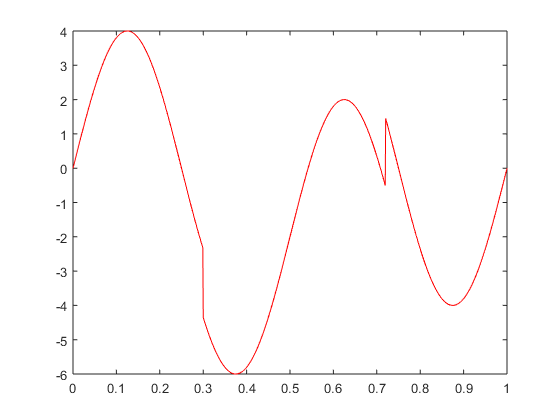

loc = linspace(0,1,2^10);
x = wnoise(3,10);
figure(5)
plot(loc,x, 'r')

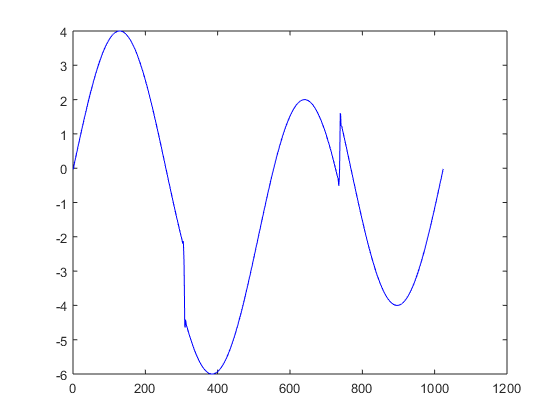

for i = 1:10
    [cA,cD] = dwt(x, 'sym4');
    x = idwt(cA,zeros(size(cA)),'sym4');
end
figure(6)
plot(x,'b')